# **Lab 6 (T1 2020) - Statistical Signal Processing**

*By Jason Ha (z5115925)*

## *Question 1*

*Suppose that *$X\left\lbrack n\right\rbrack$ is a white Gaussian noise process (WGN process) with $\mu_X =0$ and $\sigma {\;}_{X\;}^2 =0\ldotp 25$. We want to generate $K=256$ different realisations of this random process each with length $N=32$ using 'randn'. Note that in general, for a WGN with non-standard mean and standard deviation:


$$X=\mathrm{aY}+b$$


Where $Y$ is the WGN with mean and variance of 0 and 1 respectively, $a$ is the standard deviation and $b$ is the mean.$X$ is the modified WGN random process with the non-standard mean and standard deviation.

% Code to generate the WGN process. Use a matrix of size K * N:
% The 'rows' of the matrix correspond to the specific realisation while the
% columns access the particular sample in one realisation.
K = 256; % i.e. 256 different random processes Xi[n]
N = 32;  % i.e. Each Xi[n] has 32 samples in the discrete time-domain

% Declare constants for mean and std. dev:
a = sqrt(0.25);
b = 0;

% Generate the random processes:
Y = randn(K,N);

% Generate X with the modified mean and standard deviation:
X = a*Y + b;

% Print the matrix in the output window:
X

X =     0.0298   -0.1189   -0.5713    0.0441   -0.0366    0.3319   -0.5582   -0.7129   -0.3972   -0.7278    0.2143   -0.2077   -0.2919    0.6431    0.0514    0.2144    0.8225    0.2094    0.6043    0.3088   -0.2500   -0.9396    0.2856    0.6450   -0.3518    0.4832   -0.3778   -0.7522    0.3024    0.1674   -0.3150   -0.1266
    0.0124    0.5347   -0.0977   -0.5967    0.5690    0.1401    0.8337    0.2096   -0.0428   -1.3022   -0.4112   -0.6434   -0.2886    0.3879    0.3468    0.1362    0.7291   -0.0190    0.1709   -0.4795   -0.1798    0.6037   -0.3902   -0.2395   -0.1069    0.1604   -0.6752   -0.0436   -1.0140    0.0267   -0.1877   -0.2099
    0.3202    0.2146    0.5833   -0.5530   -0.3660   -0.1273    0.3664   -0.0677    0.8455   -0.6584   -0.0562    0.6744   -0.9342    0.3960    0.2367   -1.3050   -0.2280   -0.1551    0.4299    0.2938    0.0972    0.2993   -0.1661   -0.1749   -0.1412   -0.1984   -0.2839    0.2660   -0.1369   -1.1194    0.4781   -0.2123
   -0.2938   -0.0592   -0.1966   

### Part (a)

We calculate the ensemble mean (or expected value) of each column in$X$. Theoretically, we should have:


$$E\left\lbrack X\right\rbrack =E\left\lbrack \mathrm{aY}+b\right\rbrack =\mu {\;}_A E\left\lbrack Y\right\rbrack +\mu {\;}_b$$


We can simply use the *mean* function to compute this in the code cell below

% Compute the mean 
mean_X = mean(X);

% Print out the mean of each realisation:
mean_X

mean_X =    -0.0193   -0.0212    0.0178    0.0175    0.0065   -0.0136    0.0361   -0.0274    0.0095   -0.0079   -0.0092    0.0686   -0.0202   -0.0233    0.0151   -0.0091   -0.0078   -0.0432    0.0011   -0.0082   -0.0053   -0.0037    0.0017    0.0264    0.0456   -0.0160    0.0185   -0.0367    0.0374    0.0485    0.0311    0.0009


### Part (b)

We can also calculate the ensemble variance for each column which is performed in the code cell below:

% Compute the variance:
var_X = var(X);

% Print out the variance of each realisation
var_X

var_X =     0.2753    0.2137    0.2229    0.2946    0.2741    0.2209    0.2642    0.2398    0.2641    0.2854    0.2846    0.2814    0.2485    0.2293    0.2641    0.2449    0.2846    0.2558    0.2450    0.2460    0.2295    0.2669    0.2600    0.2324    0.2424    0.2069    0.2799    0.2732    0.2524    0.2381    0.2639    0.2358


### Part (c)

The autocorrelation computes the correlation of some signal and a delayed version of itself by some time-lag $\tau \;$. In continuous time, this would be:


$$R_{\mathrm{xx}} \left(t,t-\tau \;\right)=\frac{1}{T}\int_{-T/2}^{T/2\;} x\left(t\right)x\left(t-\tau \;\right)\mathrm{dt}$$


In discrete-time, the autocorrelation will take the form of an finite sum instead:


$$r_{\mathrm{xx}} \left\lbrack m\right\rbrack =\frac{1}{2N+1}\sum_{n=-N}^N x\left\lbrack n\right\rbrack x\left\lbrack n-m\right\rbrack$$


In the case of our matrix, each of the 32 columns corresponds to a specific realisation $x$ will extend to a length of $2N+1=65$ samples long. As a result, our final autocorrelation matrix will be of size $256\times 65$. We can plot the 2D heatmap of the autocorrelation matrix.

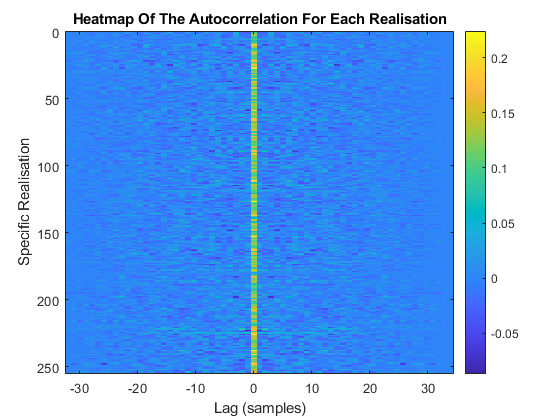

% The 'my_autocorr' is a custom function to compute the autocorrelation of
% a sequence, for each row. Initialise the autocorrelation matrix, Rxx:
Rxx = zeros([K, 2*N+1]);

% Use a for-loop to access each of the 256 rows and compute each rows
% autoccorelation. Assign to the respective row in Rxx:
for row = 1:K
    seq = X(row, :);
    Rxx(row,:) = my_autocorr(seq);
end

x = -N:1:N+2;
y = 0:255;

% We can now plot the autocorrelation matrix as a heatmap using image sc:
figure
imagesc(x,y,fftshift(Rxx))
colorbar
xlabel("Lag (samples)")
ylabel("Specific Realisation")
title("Heatmap Of The Autocorrelation For Each Realisation")

The x-axis corresponds to the lag of the delayed version of $x$. For all realisations, it is clear that at a lag of $m=0$, the signals are expected to be exactly the same and hence their autocorrelation value is expected to be the same. From this lag onwards it should be expected there is no correlation between the original sequence and the delayed sequence since there is no periodicity and the process is random. 

### Part (d)

The covariance is a measure of the joint variability of two random variables. Specifically, it is the product of their deviations from their means. In general, we have:


$$\mathrm{cov}\left(X,Y\right)=E\left\lbrack \left(X-\mu {\;}_X \right)\left(Y-\mu {\;}_Y \right)\right\rbrack =E\left\lbrack \mathrm{XY}\right\rbrack -\mu {\;}_X \mu {\;}_Y =R_{\mathrm{XY}} -\mu {\;}_x \mu {\;}_y$$


If the random variable is a vector/matrix, $X$ then we have


$$C_X =E\left\lbrack \left(\mathit{\mathbf{X}}-\mu {\;}_{\mathit{\mathbf{X}}} \right){\cdot \;\left(\mathit{\mathbf{X}}-\mu {\;}_{\mathit{\mathbf{X}}} \right)}^T \right\rbrack =R_X -\mu {\;}_{\mathit{\mathbf{X}}} \mu {\;}_{\mathit{\mathbf{X}}}^T$$


Where $R_{\mathit{\mathbf{X}}}$ computes the *correlation* of the random vector$X$and essentially measures the joint expected value of two random variables $X_i$ and $X_j$ for $i\not= j$. We are expected this to be a square and symmatric matrix. Theoretically, we are expecting ONLY the diagonal elements in the covariance matrix to be non-zero since **the covariance of two statistically independent random variables MUST be equal to zero (or at least very close to zero). **

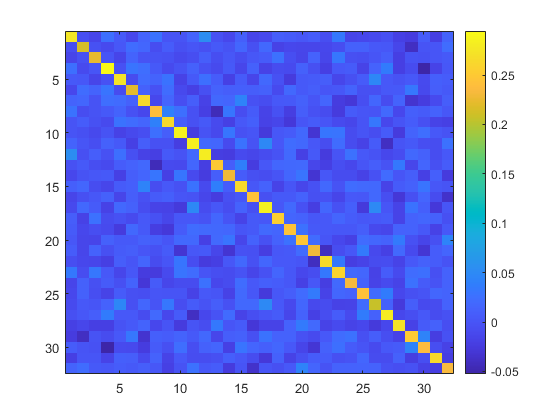

C = cov(X);

% Plot this as an image:
figure
imagesc(C)
colorbar

## Question 2

Now we want to create a brand new 1-D random process but see the use of time-averaging to compute the same statistics. Suppose we consider a single random variable in the random vector$\mathit{\mathbf{X}}$ which we will call just $X\left\lbrack n\right\rbrack$ a discrete random process. Let $X\left\lbrack n\right\rbrack$ have support $0\ldotp \ldotp \ldotp 256-1$ samples and let it be generated via a WGN process:

% Now, let N = 256. To prevent confusion, let this be N2:
N2 = 256;   % Number of samples in this single random process.

% Let X2 be the random process generated via WGN:
X2 = randn(1,256);

% Compute the mean of the signal:
mean_X2 = mean(X2);
fprintf("The mean of X2 = %f\n", mean_X2)

The mean of X2 = 0.017850



% Compute the variance of the signal:
var_X2 = var(X2);
fprintf("The variance of X2 = %f\n", var_X2)

The variance of X2 = 0.958962



% Compute the covariance:
cov_X2 = cov(X2);
fprintf("The covariance of X2 = %f\n", cov_X2)

The covariance of X2 = 0.958962


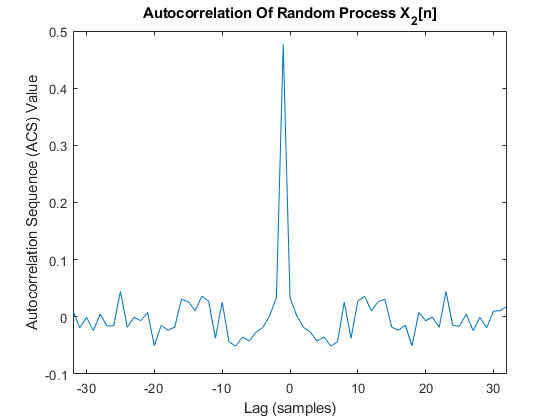


% Compute the autocorrelation of the single random process. In this case,
% it is better to visualise the autocorrelation as a graph:
autocorr_X2 = fftshift(my_autocorr(X2));
figure
plot(-256:1:256, autocorr_X2)
title("Autocorrelation Of Random Process X_2[n]")
xlim([-32, 32])
xlabel("Lag (samples)")
ylabel("Autocorrelation Sequence (ACS) Value")

## Question 3

The *Power Spectral Density (PSD) *of the random vector$X$ is the DTFT of the autocorrelation sequence $R_{\mathrm{xx}} \left\lbrack n\right\rbrack$


$$S_{\mathrm{xx}} \left(\omega \;\right)=\sum_{m=-N}^N R_{\mathrm{xx}} \left\lbrack m\right\rbrack e^{-\mathrm{jm}\omega \;}$$


### Part (b)

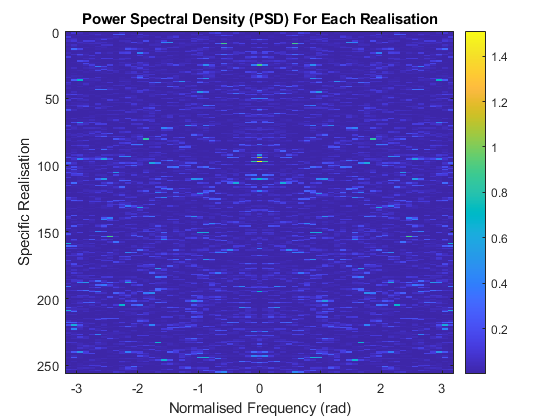

% The sample support for Sxx is still size N samples long for the K
% realisations.
Sxx_mat = zeros([K,N]);

% For each realisation we compute the FFT and store the result in Sxx_mat:
for i = 1:K
    Rxx_hat(i,:) = fft(Rxx(i,:));
    Rxx_hat(i,:) = fftshift(Rxx_hat(i,:));
end

Sxx = abs(Rxx_hat).^2;

y_ax = 0:256;
x_ax = linspace(-pi, pi, 65);

figure
imagesc(x_ax, y_ax, Sxx)
title("Power Spectral Density (PSD) For Each Realisation")
xlabel("Normalised Frequency (rad)")
ylabel("Specific Realisation")
colorbar

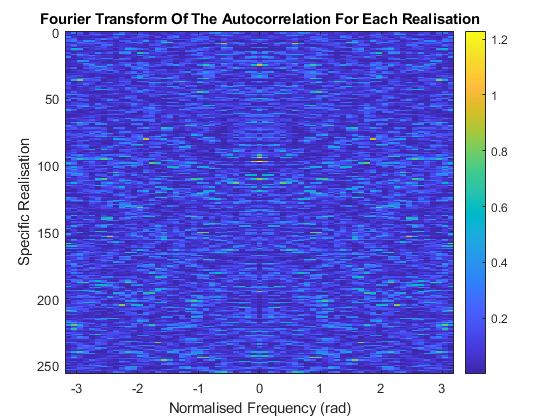


figure
imagesc(x_ax, y_ax, abs(Rxx_hat))
title("Fourier Transform Of The Autocorrelation For Each Realisation")
xlabel("Normalised Frequency (rad)")
ylabel("Specific Realisation")
colorbar

## Question 4

We perform the same procedure for the single random process with $N=256$ samples.

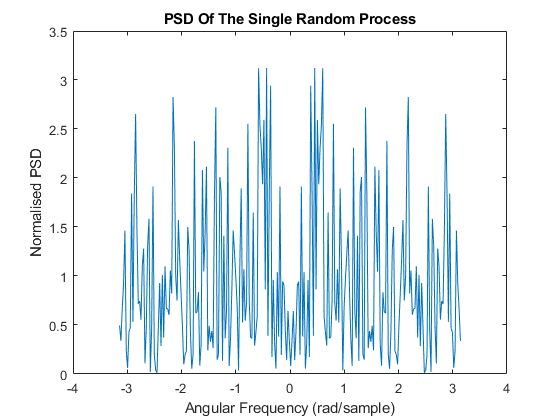

autocorr_X2_hat = fftshift(fft(X2));
Sxx_X2 = abs(autocorr_X2_hat).^2;

x_ax_X2 = linspace(-pi, pi, N2);

figure
plot(x_ax_X2, 1/length(Sxx_X2) * Sxx_X2)
title("PSD Of The Single Random Process")
xlabel("Angular Frequency (rad/sample)")
ylabel("Normalised PSD")

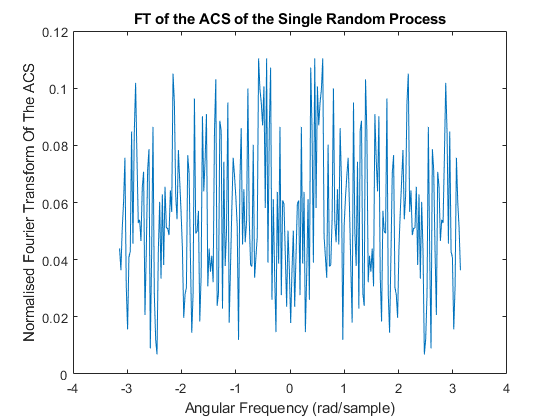


figure
plot(x_ax_X2, 1/length(autocorr_X2_hat) * abs(autocorr_X2_hat))
title("FT of the ACS of the Single Random Process")
xlabel("Angular Frequency (rad/sample)")
ylabel("Normalised Fourier Transform Of The ACS")

## Question 5

Suppose we have the following transfer function:


$$H\left(z\right)=\frac{z^2 -1\ldotp 5z+1}{z^2 -0\ldotp 4z+0\ldotp 4}=\frac{1-1\ldotp 5z^{-1} +z^{-2} }{1-0\ldotp 4z^{-1} +0\ldotp 4z^{-2} }$$


### Part (a)

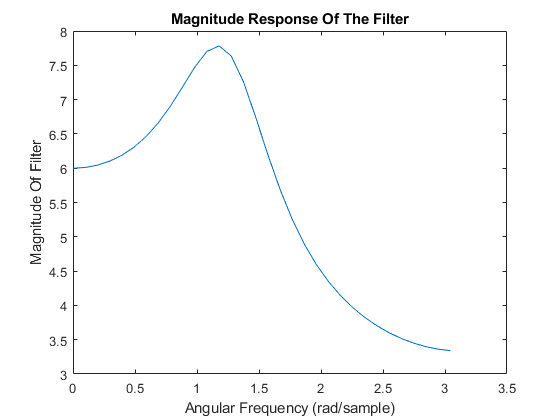

% Create arrays for the numerator and denominator:
num = [1, -1,5, 1];
den = [1, -0.4, 0.4];

% Use freqz to generate the N-point system transfer function with respect to the sequences in Part 1:
[H1,W1] = freqz(num,den,N);

% We now want to plot the magnitude and phase response of the filter:
figure
plot(W1, abs(H1))
title("Magnitude Response Of The Filter")
xlabel("Angular Frequency (rad/sample)")
ylabel("Magnitude Of Filter")

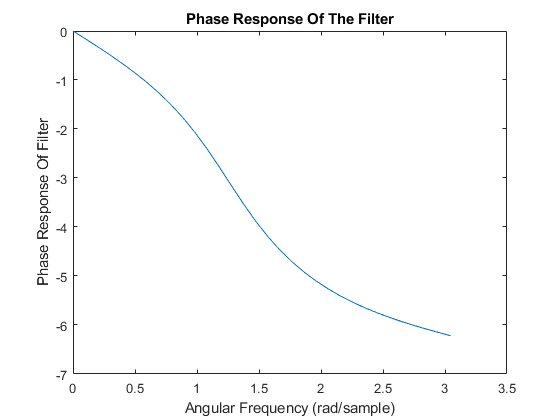


% Plotting the phase response of the filter:
figure
plot(W1, unwrap(angle(H1)))
title("Phase Response Of The Filter")
xlabel("Angular Frequency (rad/sample)")
ylabel("Phase Response Of Filter")

### Part (c)(i)

Now applying the filter onto each of the 256 realisations from Part 1:

Xf  = zeros(K, N);

for i = 1:K
    Xf(i,:) = filter(num,den,X(i,:));
end

% Computing the same statistics:
mean_Xf = mean(Xf)

mean_Xf =    -0.0193   -0.0096   -0.0538   -0.1434    0.0211    0.1511    0.1515   -0.1247    0.0934   -0.0310   -0.0310    0.0478   -0.1110    0.2673    0.1574   -0.2048   -0.0915   -0.0203    0.0249   -0.2149   -0.1306   -0.0045    0.0212    0.0109    0.0200    0.0760    0.3111    0.0042    0.0276   -0.1448    0.0638    0.3330


var_Xf = var(Xf)

var_Xf =     0.2753    0.3189    5.4337    6.8935    6.5335    8.8480    8.8890    7.0791    8.2231    7.2359    8.5796    8.9208    8.2303    9.2188    7.7735    7.6286    8.3591    7.9552    8.8526    8.5765    8.1009    8.3266    8.0222    6.6059    9.4383    7.9463    8.5040    7.7438    8.5168    8.4691    7.7322    8.9438



% Computing the autocorrelation for each realisation:
autocorr_Xf = zeros(K, 2*N+1)

autocorr_Xf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     

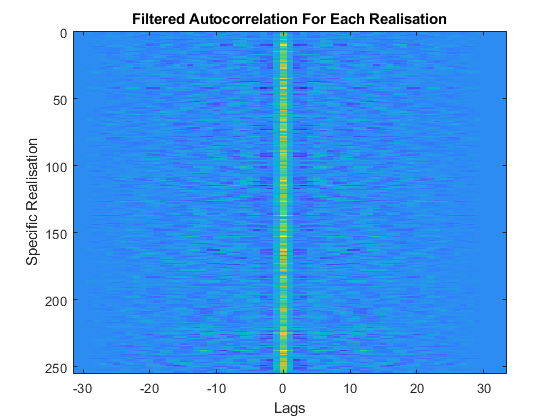

for i = 1:K
    autocorr_Xf(i,:) = my_autocorr(Xf(i,:));
end

% Plotting the autocorrelation for each realisation
figure
imagesc(-31:33, 0:255, fftshift(autocorr_Xf))
title("Filtered Autocorrelation For Each Realisation")
xlabel("Lags")
ylabel("Specific Realisation")

A noticible observation is that the filter has made all the realisations similar for a larger number of lags compared to Part 1.